magnificationFactor = 0.6;
tifPic2 = imresize(tifPic,magnificationFactor);

figure
subplot(1,3,1)
imagesc(tifPic2)
hold on 
plot(ypts,xpts,'w.','Markersize',2)
colormap jet
axis equal

topoIm = (polarMap(meanpolar{2},95));
subplot(1,3,2)
imagesc(topoIm)
hold on 
plot(ypts,xpts,'w.','Markersize',2)
axis equal

sizeTifPic2 = size(tifPic2)
sizeTopoIm = size(topoIm)
sizeBaselinedActIm = size(baselinedActIm)



magnificationFactor = 0.35;
resizeTopoIm = imresize(topoIm,magnificationFactor);

figure

subplot(1,2,1)
%imagesc(resizeTopoIm)
imagesc(resizeTopoIm(yPtsCrop(1):yPtsCrop(2),xPtsCrop(1):xPtsCrop(2),:));
%imagesc(topoIm(yPtsCrop(1):yPtsCrop(2),xPtsCrop(1):xPtsCrop(2),:));
%imagesc(topoIm(yPtsCrop(1):yPtsCrop(2),xPtsCrop(1)+30:xPtsCrop(2)+50,:));
ylim([-20 150])
%axis equal

subplot(1,2,2)
imagesc(baselinedActIm)
ylim([-20 150])
%axis equal



figure

% TOPO MAP w/AREA BOUNDARIES
% meanpolar made in do_topography
topoIm = (polarMap(meanpolar{2},95));
subplot(1,4,1)
imagesc(topoIm)
hold on
plot(ypts,xpts,'w.','Markersize',2)
axis equal
    
% RAW TIF SHOWING BLOOD VESSELS
% select tif file
[f p] = uigetfile('*.tif','thresh tif file');
tifPic = imread(fullfile(p,f));
tifPic = flip(tifPic,2);
subplot(1,4,2)
imagesc(tifPic)
axis equal

% IMAGE FOR PICKING POINTS
% the function pickPeakActIm4Points() generates an output var called
% baselinedActIm, which is needed for the figure to pick 5 points
stdMap = std(df(:,:,1:10:end),[],3);
subplot(1,4,3)
imagesc(stdMap,range)
axis equal
    
% CROPPED
subplot(1,4,4)
imagesc(baselinedActIm,range)
axis equal

%colormap jet
    
sizeTopoIm = size(polarMap(meanpolar{2},95))
sizeTifPic = size(tifPic)
%sizeDfUnCropped = size(df) 
sizeStdMap = size(stdMap)
sizePeakActIm = size(baselinedActIm)



sizeTifPic = size(tifPic)

sizeTifPic =    540   640


sizeTopoIm = size(topoIm)

sizeTopoIm =    260   320     3


sizeStdMap = size(stdMap)

sizeStdMap =    185   227


sizePeakActIm = size(baselinedActIm)

sizePeakActIm =    120   100


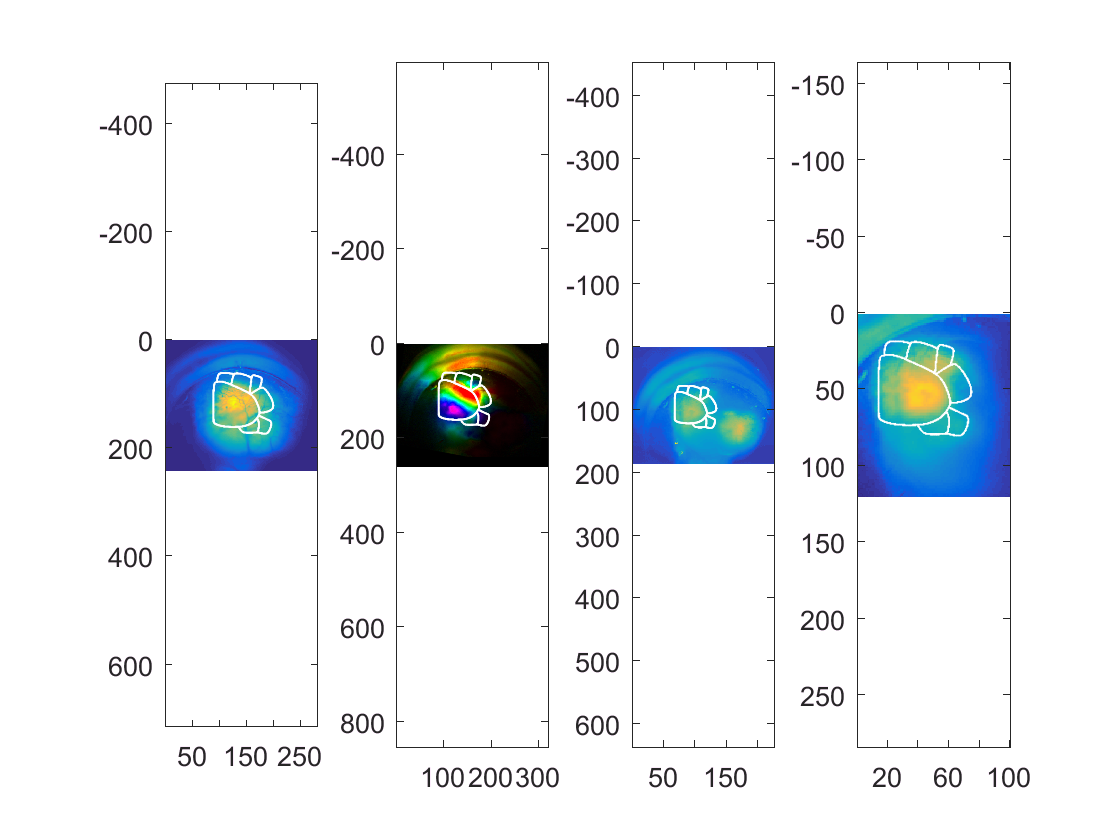


figure

% RAW TIF SHOWING BLOOD VESSELS
% select tif file
%[f p] = uigetfile('*.tif','thresh tif file');
%tifPic = imread(fullfile(p,f));
%tifPic = flip(tifPic,2);
resizeTifPic = imresize(tifPic,0.5);
resizeTifPic = resizeTifPic(30:end,40:end);
subplot(1,4,1)
imagesc(resizeTifPic)
hold on
plot(ypts,xpts,'w.','Markersize',2)
axis equal

% TOPO MAP w/AREA BOUNDARIES
% meanpolar made in do_topography
topoIm = (polarMap(meanpolar{2},95));
subplot(1,4,2)
imagesc(topoIm)
hold on
plot(ypts,xpts,'w.','Markersize',2)
axis equal

% IMAGE FOR PICKING POINTS
% the function pickPeakActIm4Points() generates an output var called
% baselinedActIm, which is needed for the figure to pick 5 points
stdMap = std(df(:,:,1:10:end),[],3);
%stdMap = stdMap(5:end,:);
subplot(1,4,3)
imagesc(stdMap,range)
hold on
resizeXpts = (xpts*0.6)+25;
resizeYpts = (ypts*0.6)+15;
%plot(ypts,xpts,'w.','Markersize',2)
plot(resizeYpts,resizeXpts,'w.','Markersize',2)
axis equal
    
% CROPPED
subplot(1,4,4)
imagesc(baselinedActIm,range)
axis equal
hold on
resizeXpts = (xpts*0.55)-15;%-xPtsCrop(2);
resizeYpts = (ypts*0.55)-35;%-yPtsCrop(2);
plot(resizeYpts,resizeXpts,'w.','Markersize',2)


%colormap jet
    
% sizeResizeTifPic = size(resizeTifPic)
% sizeTopoIm = size(topoIm)
% sizeStdMap = size(stdMap)
% sizePeakActIm = size(baselinedActIm)

